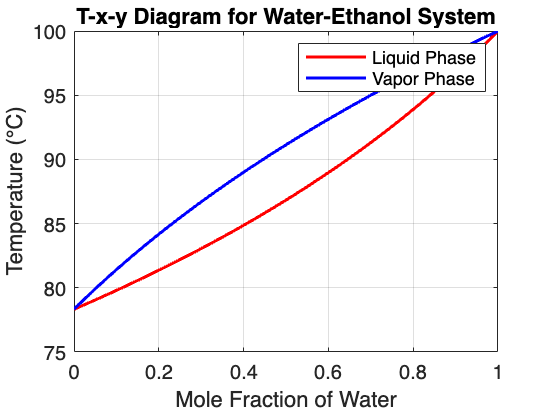

% Part 1
% Antoine equations 
function vapPw = vapPw(T)
vapPw = 10^(8.07131 - 1730.63/(T + 233.426)); % Water
end

function vapPe = vapPe(T)
vapPe = 10^(8.2133 - 1652.05/(T + 231.48)); % Ethanol
end

% System Parameters
P_t = 760;                     % Total pressure in mmHg
x_liq = 0:0.01:1;              % Mole fraction of water in liquid phase
y_vap = zeros(length(x_liq), 1); % Mole fraction of water in vapor phase
Tl_calc = zeros(length(x_liq), 1); % Liquid-phase temperatures
Tv_calc = zeros(length(y_vap), 1); % Vapor-phase temperatures
T_guess = 89;                  % Guess for temperature b/w Ethanol b.p (78.23) and Water b.p (100)

for i = 1:length(x_liq)
    % Liquid phase
    eqnl = @(T) P_t - x_liq(i)*vapPw(T) - (1 - x_liq(i))*vapPe(T);
    Tl_calc(i, 1) = fzero(eqnl, T_guess); % Solve for liquid-phase temperature

    % Updating initial guess 
    T_guess = Tl_calc(i, 1);

    % Calculating vapor phase mole fraction
    y_vap(i, 1) = (x_liq(i) * vapPw(T_guess)) / P_t;
end


% Plotting the t-x-y diagram
figure;
plot(x_liq, Tl_calc, 'r-', 'LineWidth', 1.5); % Bubble point
hold on;
plot(y_vap, Tl_calc, 'b-', 'LineWidth', 1.5); % Dew point
xlabel("Mole Fraction of Water");
ylabel("Temperature (°C)");
title("T-x-y Diagram for Water-Ethanol System");
legend("Liquid Phase", "Vapor Phase");
grid on;
xlim([0,1])

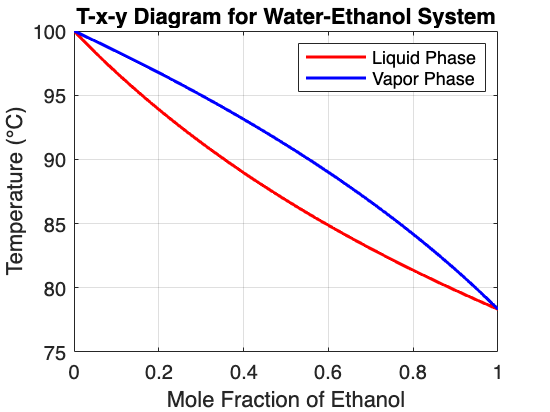


figure;
plot(1-x_liq, Tl_calc, 'r-', 'LineWidth', 1.5); % Bubble point
hold on;
plot(1-y_vap, Tl_calc, 'b-', 'LineWidth', 1.5); % Dew point
xlabel("Mole Fraction of Ethanol");
ylabel("Temperature (°C)");
title("T-x-y Diagram for Water-Ethanol System");
legend("Liquid Phase", "Vapor Phase");
grid on;
xlim([0,1])

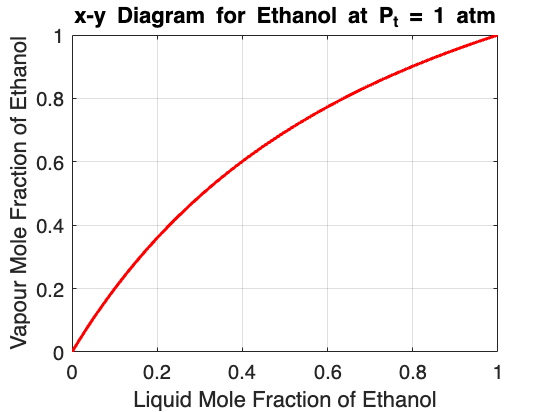

%Part 2
figure;
plot(1-x_liq, 1-y_vap, 'r-', 'LineWidth', 1.5) %x_liq and y_vap correspond to water so 1-...
xlabel("Liquid Mole Fraction of Ethanol");
ylabel("Vapour Mole Fraction of Ethanol");
title("x-y Diagram for Ethanol at P_t = 1 atm")
grid on;
ylim([0,1])

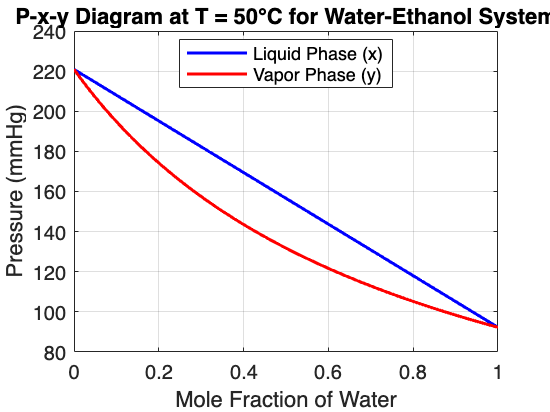

% Part 3
P_w_c = vapPw(50); %water vapour pressure @ T = 50
P_e_c = vapPe(50); %ethanol vapour pressure @ T = 50

P_c = zeros(length(x_liq), 1); %total pressure @ T = 50
y_vap_c = zeros(length(x_liq), 1);
for i = 1:length(x_liq)
    P_c(i, 1) = x_liq(i)*P_w_c + (1-x_liq(i))*P_e_c; % Raoult's Law
    y_vap_c(i, 1) = x_liq(i)*P_w_c/P_c(i,1); % vapour pressure
end

figure;
plot(x_liq, P_c, 'b-', 'LineWidth', 1.5); hold on;
plot(y_vap, P_c, 'r-', 'LineWidth', 1.5);
xlabel('Mole Fraction of Water');
ylabel('Pressure (mmHg)');
title('P-x-y Diagram at T = 50°C for Water-Ethanol System');
legend('Liquid Phase (x)', 'Vapor Phase (y)', 'Location', 'Best');
grid on;
xlim([0,1])